## load and initialize

addpath myFunction\myftn
clearvars -except mapCD
fn = 'RawData\1T-TaS2(point defect)\mapCD.mat';
loadif(fn);

fldNm = 1×1 cell array
    {'mapCD'}



Your variables are:

fldNm  fn     mt     



ans = 'already'

load RawData\'1T-TaS2(point defect)'\vDos.mat vDos

## Survey local maxima to define peak

1) it is effectively define positive band and negative band

2) un expected in gap state in T_A

3) weak peak in T_C are not found by 

gr  = groot();
gr.Units = "normalized";
mp = gr.MonitorPositions;
f1 = figure(1);
f1.Units  = "normalized";
f1.Position = secondNormalization(mp(3,:),[0 0 .3 .3]);
f1.Visible = "on";

clrs = ['r' 'g'];
nm = ["T_C","T_A"];
V = mapCD.V;
tiledlayout(2,1, 'Padding', 'none', 'TileSpacing', 'none');
for p = 1:2
    g = smm(mapCD.dt(p).G);
    nexttile;
    plot(V,g,Color=clrs(p),LineWidth=3)
    xlim([-1 1]*0.65)
    xticks(-0.6:0.1:0.6)
    
    box on
    grid on
    xlabel('Sample bias(mV)')
    vs = V(islocalmax(g))
    xlns = xline(vs,Color=clrs(p))
    set(xlns,{'Label'},transpose(cellstr(string(vs))))
    legend(nm(p))
end

vs =    -0.7240   -0.5930   -0.4790   -0.3950   -0.0620    0.1310    0.5740


xlns =   7×1 ConstantLine array:

  ConstantLine
  ConstantLine
  ConstantLine
  ConstantLine
  ConstantLine
  ConstantLine
  ConstantLine


vs =    -0.5930   -0.3700   -0.1640    0.0840    0.2420    0.5630


xlns =   6×1 ConstantLine array:

  ConstantLine
  ConstantLine
  ConstantLine
  ConstantLine
  ConstantLine
  ConstantLine


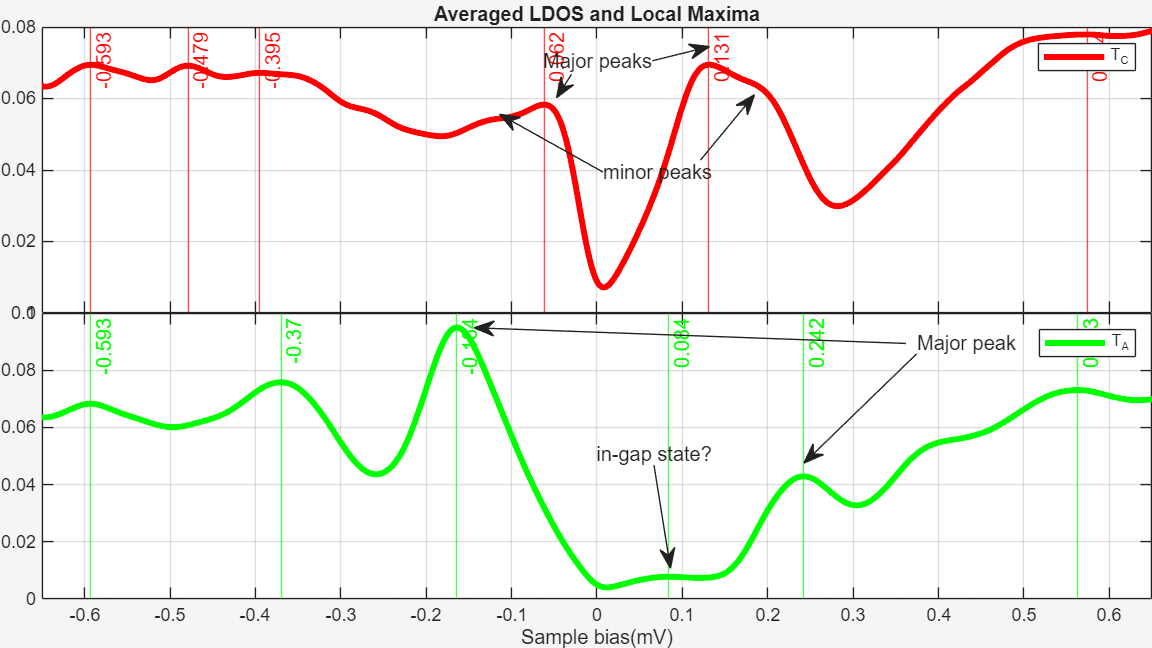

annotation("textarrow", [0.7956 0.6979], [0.4538 0.2854], "String", "Major peak")
annotation("textarrow", [0.5677 0.582], [0.2821 0.123], "String", "in-gap state?")
annotation("textarrow", [0.5664 0.6159], [0.9062 0.9281], "String", "Major peaks")
annotation("textarrow", [0.5234 0.4336], [0.7345 0.8237], "String", "minor peaks")
annotation("arrow", [0.7865 0.4115], [0.47 0.4942])
annotation("arrow", [0.4961 0.4831], [0.8853 0.8492])
annotation("arrow", [0.6081 0.6549], [0.7531 0.8538])
nexttile(1)
title("Averaged LDOS and Local Maxima")

## 2nd Derivative information to find buried peak

It is not that useful...

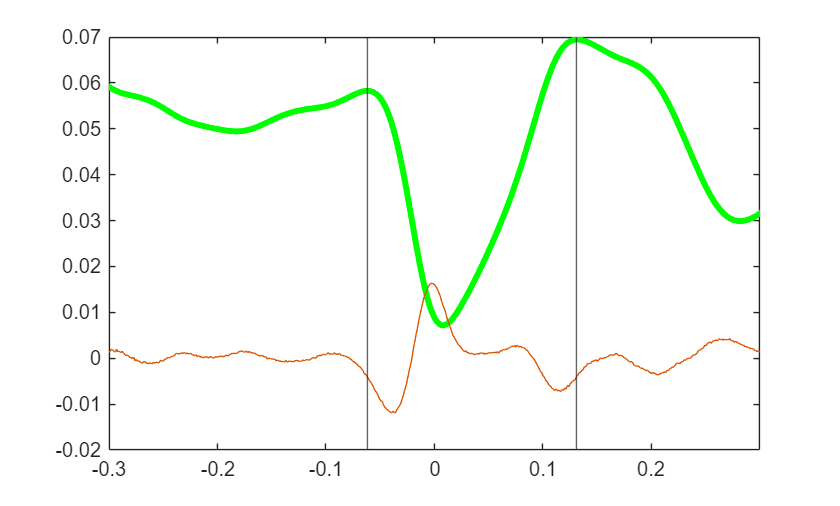

close
g = smm(mapCD.dt(1).G);
plot(V,g,Color=clrs(p),LineWidth=3)
hold on
plot(V,del2(g)*1000)
hold off
xlim([-1 1]*.3)
xline(V(islocalmax(g)))

## LDOS Histrogram vs LDOS Average

### original

1) gap-like features are more noticable in LDOS Histogram

2) minor side peaks are more visible in LDOS Histogram

close
gr = groot();
gr.Units = "normalized";
mp = gr.MonitorPositions;
f1 = figure(1);
f1.Units  = "normalized";
f1.Position = secondNormalization(mp(3,:),[0 0 .3 .3]);
f1.Visible = "on";

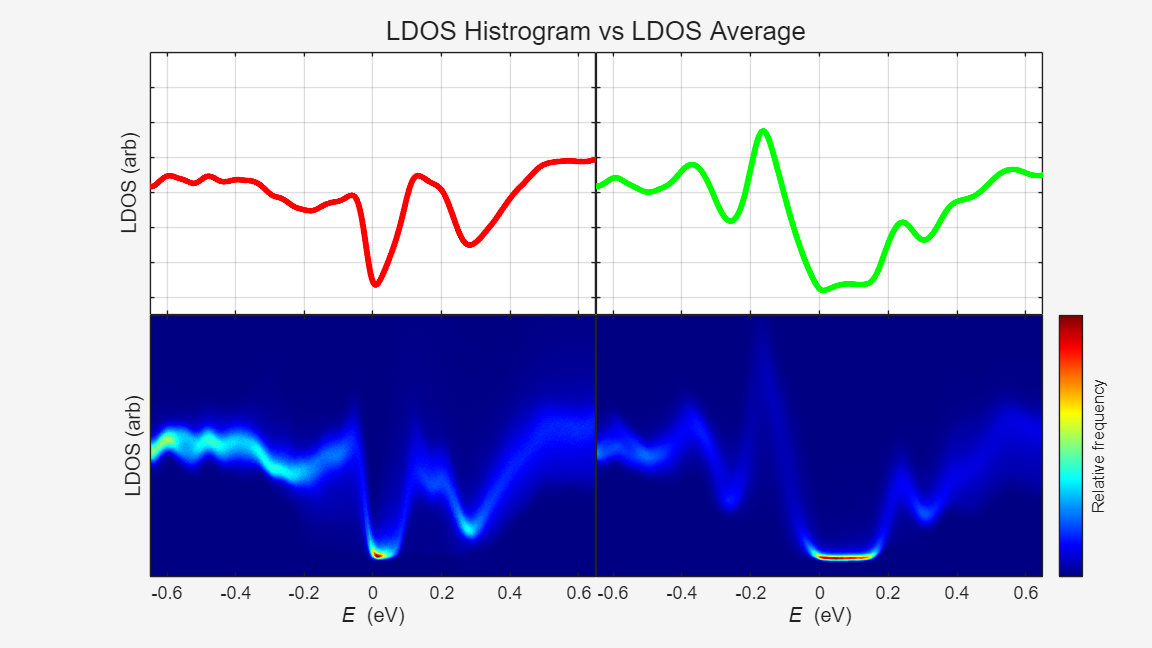

tiledlayout(2,2, 'Padding', 'loose', 'TileSpacing', 'none');
V = mapCD.V;

for isb = 1:2
    for jsb = 1:2
        % g = smm(mapCD.dt(p).G);
        nexttile;
        sbs(isb,jsb) = gca();
        if isb == 1
            g = smm(mapCD.dt(jsb).G);
            plot(V,g,Color=clrs(jsb),LineWidth=3)            
            grid on
            if jsb == 2
                
            end
        elseif isb == 2
            drawVhis(vDos.dt(:,:,jsb),V,vDos.binCntr);
            xlim([-1 1]*0.65)
            colormap jet 
            box on
            % hold on
            % g = smm(mapCD.dt(jsb).G);
            % plot(V,g,Color=clrs(jsb),LineWidth=3)            
            % hold off
            if jsb == 1
            elseif jsb == 2
                h = colorbar;
                set(h,'Ticks',[]);
                h.Label.String = 'Relative frequency';
            end
            xlabel('{\itE} (eV)')
        end
        if jsb == 1
            ylabel('LDOS (arb)')
        end
        xlim([-1 1]*0.65)
        ylim([-0.01 0.14])
        yticklabels([])
    end
end
sgtitle('LDOS Histrogram vs LDOS Average')

% gr.Children

### ver2: overlap

discrepancy  between average and histogram is due to difference between mean and mod

f1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9608 0.9608 0.9608]
    Position: [0 0 0.3000 0.3000]
       Units: 'normalized'

  Show all properties


f1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9608 0.9608 0.9608]
    Position: [0 0 0.3000 0.3000]
       Units: 'normalized'

  Show all properties


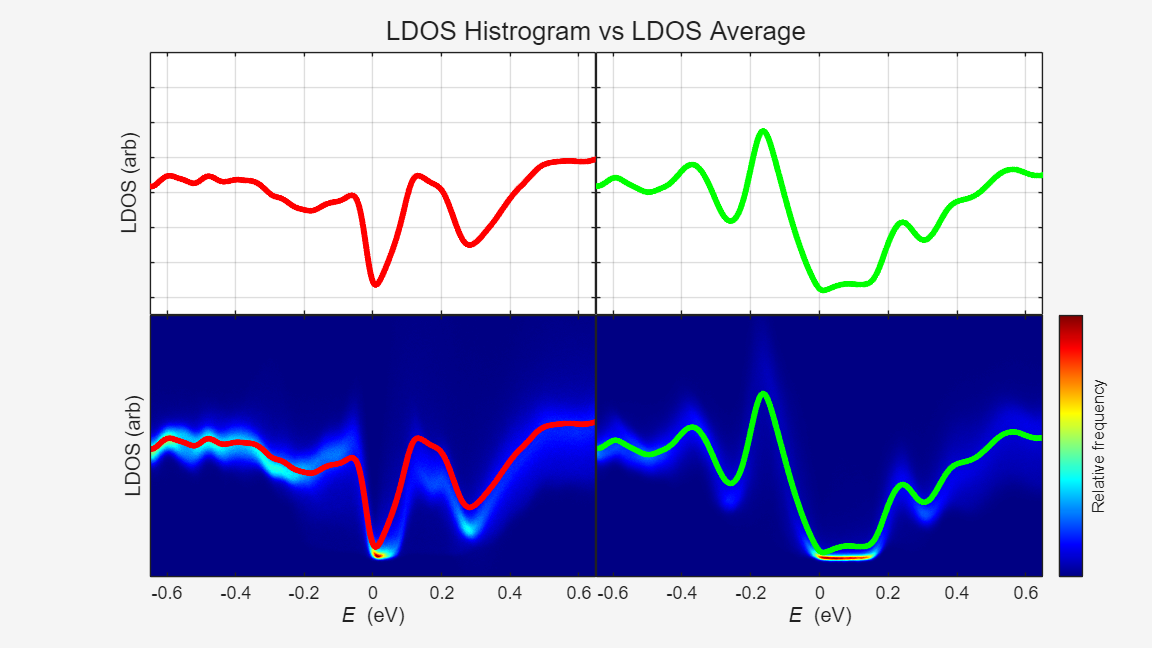

for iPhase = 1:2
    f1.CurrentAxes = sbs(2,iPhase)
    hold on
    g = smm(mapCD.dt(iPhase).G);
    plot(V,g,Color=clrs(iPhase),LineWidth=3)
    hold off
end

ver3: colormap Change to highlight in-gap state

clims = {sbs(2,:).CLim}

clims = 1×2 cell array
    {[0 5479]}    {[0 13251]}


sbs(2,1).CLim = clims{1}*.1

sbs =   2×2 Axes array:

    Axes    Axes
    Axes    Axes


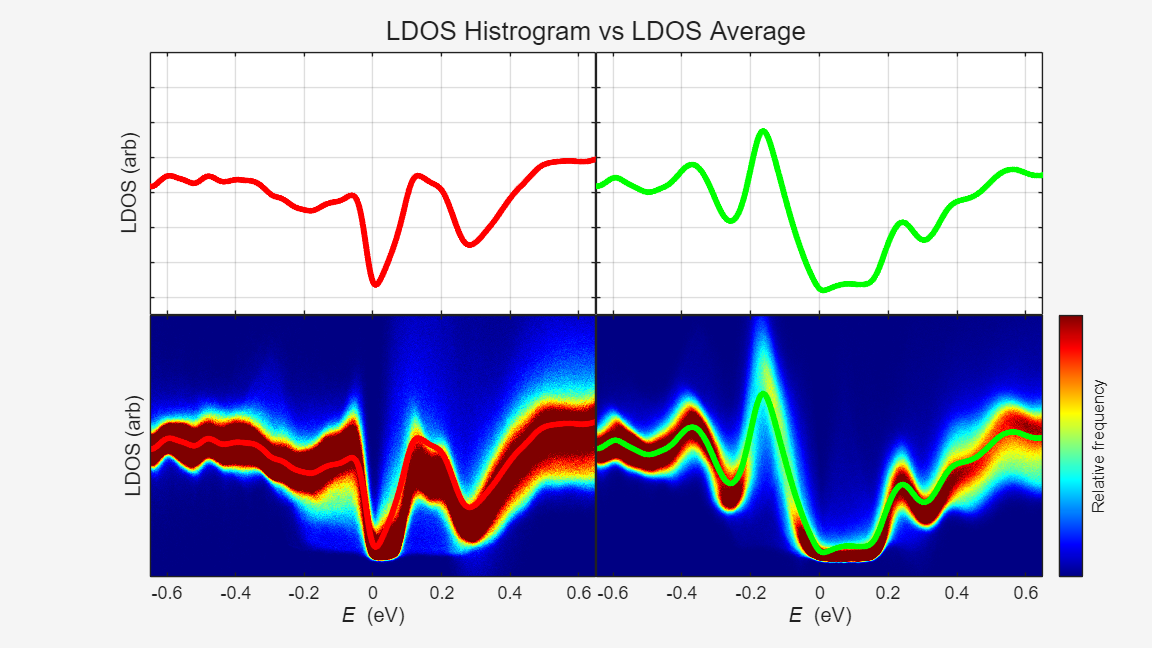

sbs =   2×2 Axes array:

    Axes    Axes
    Axes    Axes


sbs(2,2).CLim = clims{2}*.1

ver4: xline

xlss{1,1} = [-0.127 -0.062 0.05 0.131 .196]

xlss = 2×2 cell array
    {[-0.1270 -0.0620 0.0500 0.1310 0.1960]}    {5×1 cell}
    {[               -0.1640 0.0840 0.2420]}    {3×1 cell}


xlss{1,2} = {'n-minor','n-major','p-in','p-major','p-minor'}'

xlss = 2×2 cell array
    {[-0.1270 -0.0620 0.0500 0.1310 0.1960]}    {5×1 cell}
    {[               -0.1640 0.0840 0.2420]}    {3×1 cell}


xlss{2,1}  = [-0.164 .084 .242]

xlss = 2×2 cell array
    {[-0.1270 -0.0620 0.0500 0.1310 0.1960]}    {5×1 cell}
    {[               -0.1640 0.0840 0.2420]}    {3×1 cell}


xlss{2,2} = {'n-major','p-in','p-major'}'

xlss = 2×2 cell array
    {[-0.1270 -0.0620 0.0500 0.1310 0.1960]}    {5×1 cell}
    {[               -0.1640 0.0840 0.2420]}    {3×1 cell}


xlns =   5×1 ConstantLine array:

  ConstantLine    (n-minor)
  ConstantLine    (n-major)
  ConstantLine    (p-in)
  ConstantLine    (p-major)
  ConstantLine    (p-minor)


xlns =   5×1 ConstantLine array:

  ConstantLine    (n-minor)
  ConstantLine    (n-major)
  ConstantLine    (p-in)
  ConstantLine    (p-major)
  ConstantLine    (p-minor)


xlns =   3×1 ConstantLine array:

  ConstantLine    (n-major)
  ConstantLine    (p-in)
  ConstantLine    (p-major)


xlns =   3×1 ConstantLine array:

  ConstantLine    (n-major)
  ConstantLine    (p-in)
  ConstantLine    (p-major)


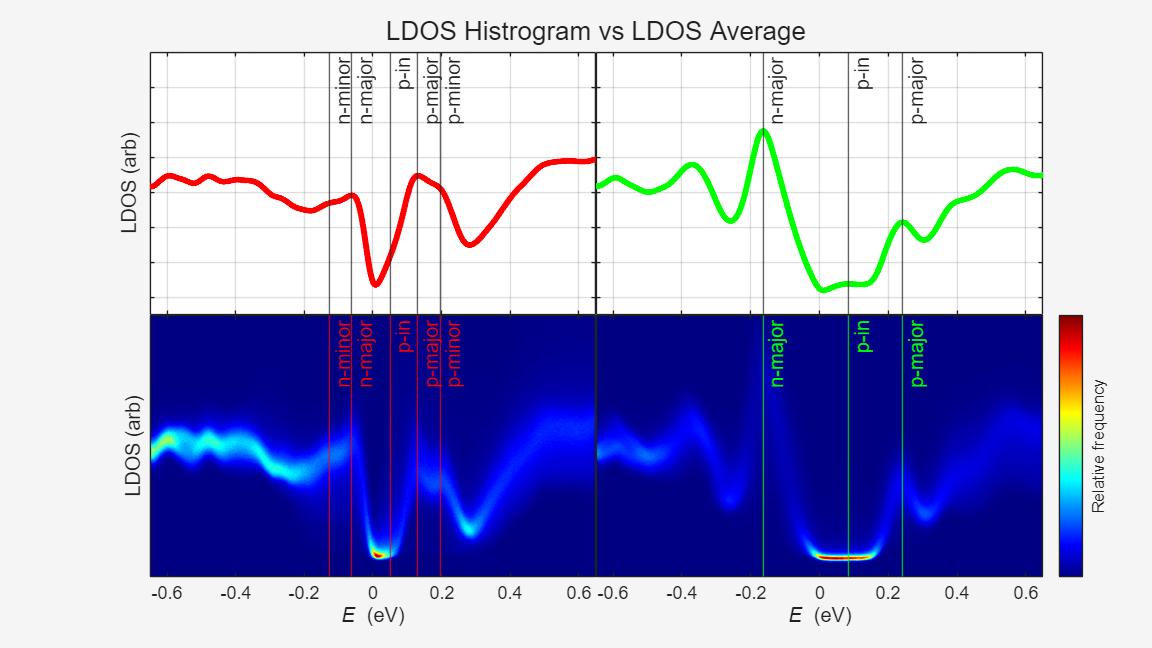

for iPhase = 1:2
    for isb = 1:2
        set(gcf(),"CurrentAxes",sbs(isb,iPhase))
        xlns = xline(xlss{iPhase,1})
        set(xlns,{'Label'},xlss{iPhase,2})
        if isb==2;set(xlns,'Color',clrs(iPhase)) ;end
    end
end

Create Random Sampling points

rng(41);
rand_nums = rand(50,2,2);
szs(:,:,1) = size(mapCD.dt(1).Z);
szs(:,:,2) =  size(mapCD.dt(2).Z);
rand_pxls = round(rand_nums.*szs);

for p = 1:2
    subplot(1,2,p)
    imgfoo = mapCD.dt(p).Z;
    views(imgfoo)
    colormap('gray')
    hold on
    plot(rand_pxls(:,1,p),rand_pxls(:,2,p),'ro')
    hold off
    if p == 1
        tmpClim = gca().CLim
    elseif p == 2
        ax = gca();
        ax.CLim = tmpClim
    end
end

tmpClim =     0.0167    0.2532


ax =   Axes with properties:

             XLim: [0.5000 731.5000]
             YLim: [0.5000 621.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5703 0.1100 0.3347 0.8150]
            Units: 'normalized'

  Show all properties


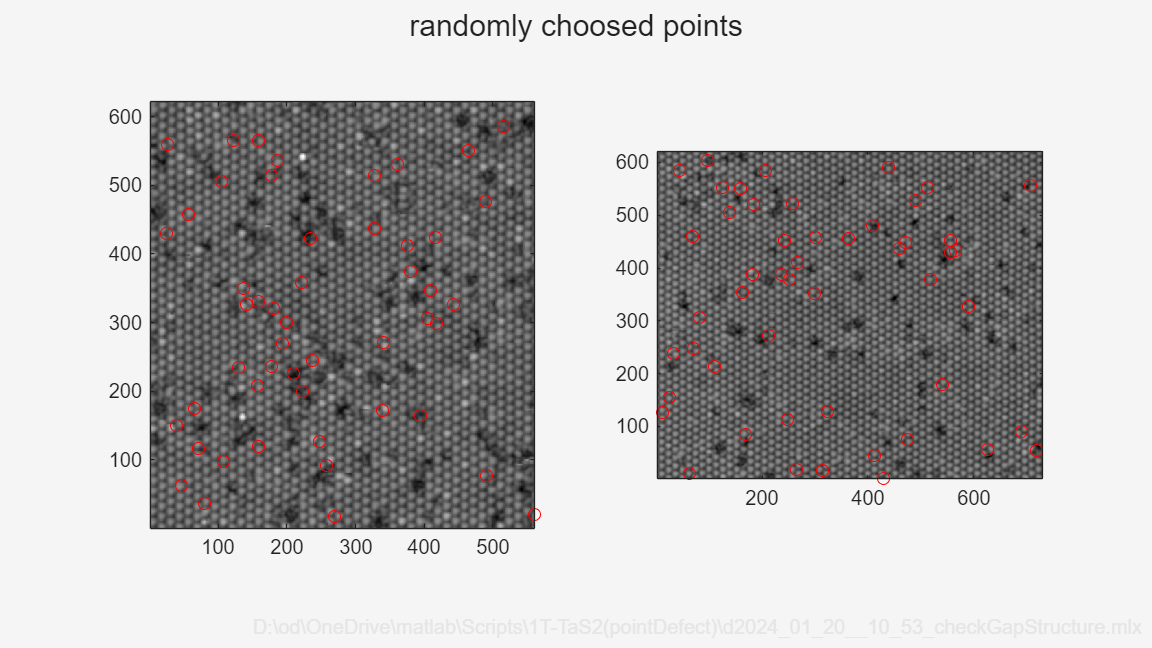

sgtitle('randomly choosed points')
waterMark()

ph = 2

ph = 2

ipoint = 1

ipoint = 1

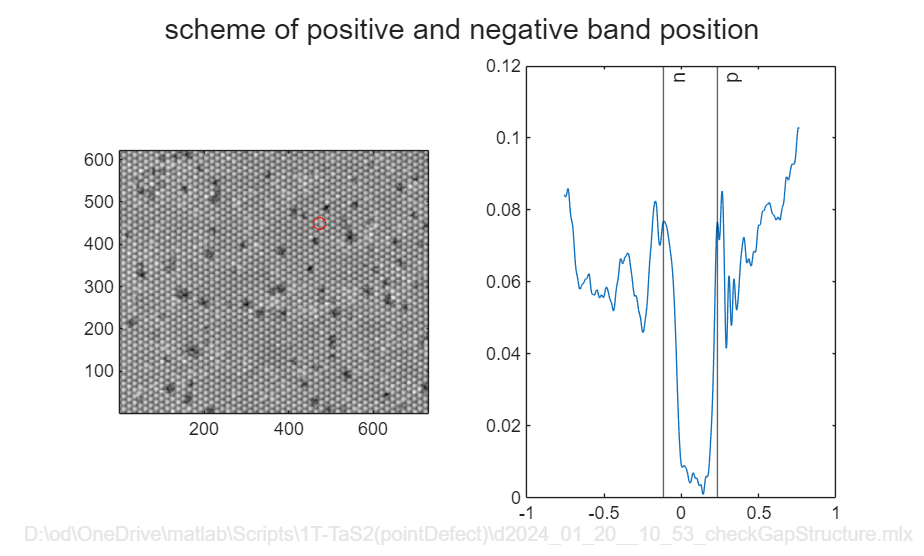

xpxl = rand_pxls(ipoint,1,ph);
ypxl = rand_pxls(ipoint,2,ph);
close 
subplot(1,2,1)
imgfoo = mapCD.dt(p).Z;
views(imgfoo)
colormap('gray')
hold on
plot(xpxl,ypxl,'ro')
hold off


subplot(1,2,2)
imgfoo = mapCD.dt(p).Z;
V = mapCD.V;
g = squeeze(mapCD.dt(ph).G(xpxl,ypxl,:));
Gap_p = mapCD.dt(ph).Gap_p(xpxl,ypxl);
Gap_n = mapCD.dt(ph).Gap_n(xpxl,ypxl);
plot(V,g)
xline(Gap_p,'-','p')
xline(Gap_n,'-','n')

sgtitle('scheme of positive and negative band position')
waterMark()

ph = 1

ph = 1

msb = 6

nsb = 8

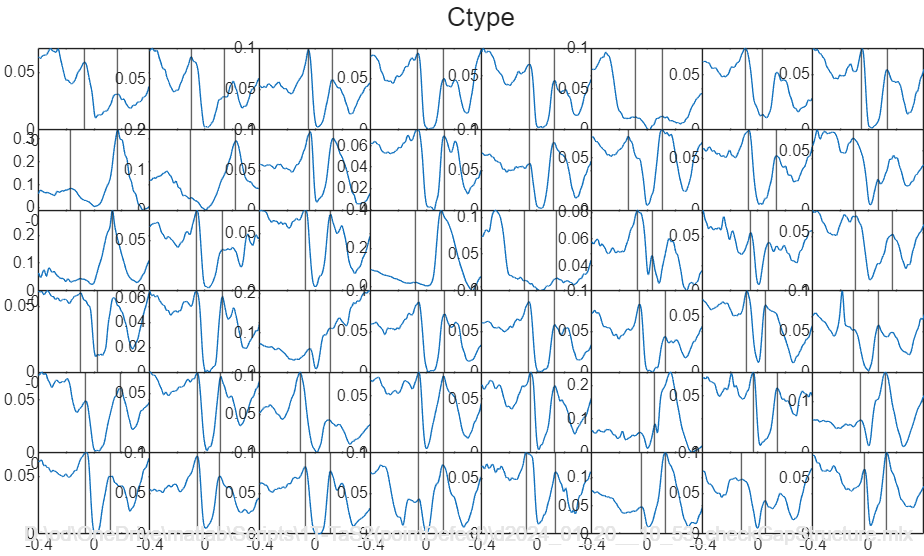

function multpleDraw(mapCD,rand_pxls,ph)
V = mapCD.V;
msb = 6
nsb = 8
sgtns = ["Ctype" 'Atype'];
tiledlayout(msb,nsb, 'Padding', 'none', 'TileSpacing', 'none'); 
for i=1:msb*nsb    
    nexttile
    xpxl = rand_pxls(i,1,ph);
    ypxl = rand_pxls(i,2,ph);
    
    g = squeeze(mapCD.dt(ph).G(xpxl,ypxl,:));
    Gap_p = mapCD.dt(ph).Gap_p(xpxl,ypxl);
    Gap_n = mapCD.dt(ph).Gap_n(xpxl,ypxl);
    plot(V,g); 
    xline(Gap_p,'-')
    xline(Gap_n,'-')
    xlim([-1 1]*0.4)
end
sgtitle(sgtns(ph))
waterMark()
end
multpleDraw(mapCD,rand_pxls,1)

msb = 6

nsb = 8

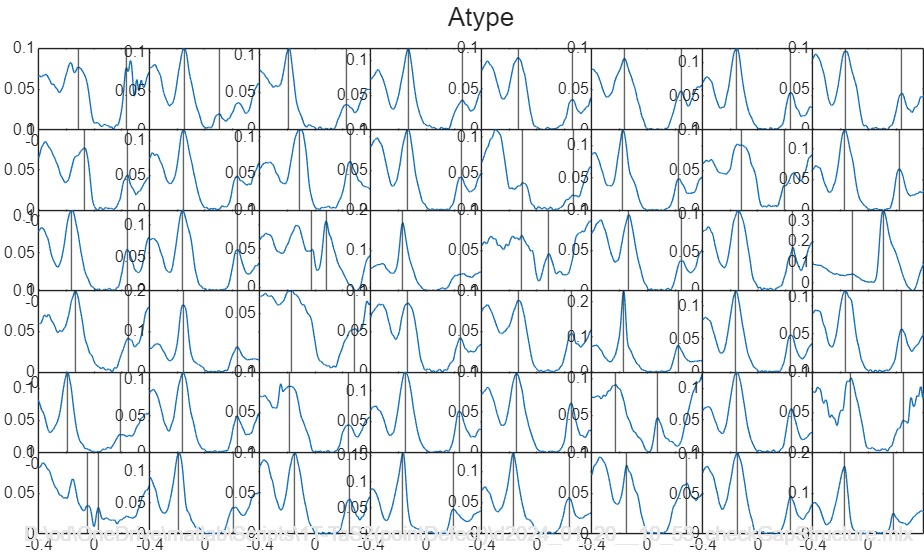

multpleDraw(mapCD,rand_pxls,2)